# Stone ID classification

MathWorks Consulting 2022

## Round 1 

### Import Dataset

tic
x=1;
x1 = 1;
sensitivity=table();
specificity=table();
datestr(now, 'dd/mm/yy-HH:MM') % 5 hrs ahead

ans = '06/11/23-22:19'

sensitivity1=table();
specificity1=table();


rootDir = "D:\April_17_2023\P12484-master-stoneID_classification\stoneID_classification";

dslocation = fullfile(rootDir, "data", "XL_BB@3mm/LED AB ON/");
datadescription = 'AvgcleavedBB@3mm'; 
distanceRange = "TwoToFour";
[dataAll, dataSummary] = ops.import.readCSV( dslocation, IncludeSubfolders=true);

% Add all folders to path
addpath(genpath(rootDir))
dataAll.Response = dataAll.TargetType;

% Cubic Spline Interpolation 

x = str2double(dataAll{1,:});
y = dataAll;

xx = linspace(400, 940, 2048);




### Train classifiers

% Specify integration time
% integraTime = 0.5;
% profile off; profile on;
%allIntTimes = unique(dataAll.IntegrationTimeUsed);
%allIntTimes = allIntTimes(4);
% integra = [1, 50, 75, 150, 250, 350];
% model1list ={};
% model2list= {};
% for i = 1:length(integra)
%     [model1, model2] = ops.trainStoneClassifiers(dataAll, integra(i));
%     fname{i} = sprintf('model10_%d%s%s%s.mat', integra(i), datadescription, distanceRange, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'));
%     model1list{i} = model1;
%     model2list{i} = model2;
% end

allIntTimes = 1%[50, 75, 250, 150, 350];

allIntTimes = 1

Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc
Running: tree
Running: discr
Running: knn
Running: svm
Running: ensemble
Running: ecoc


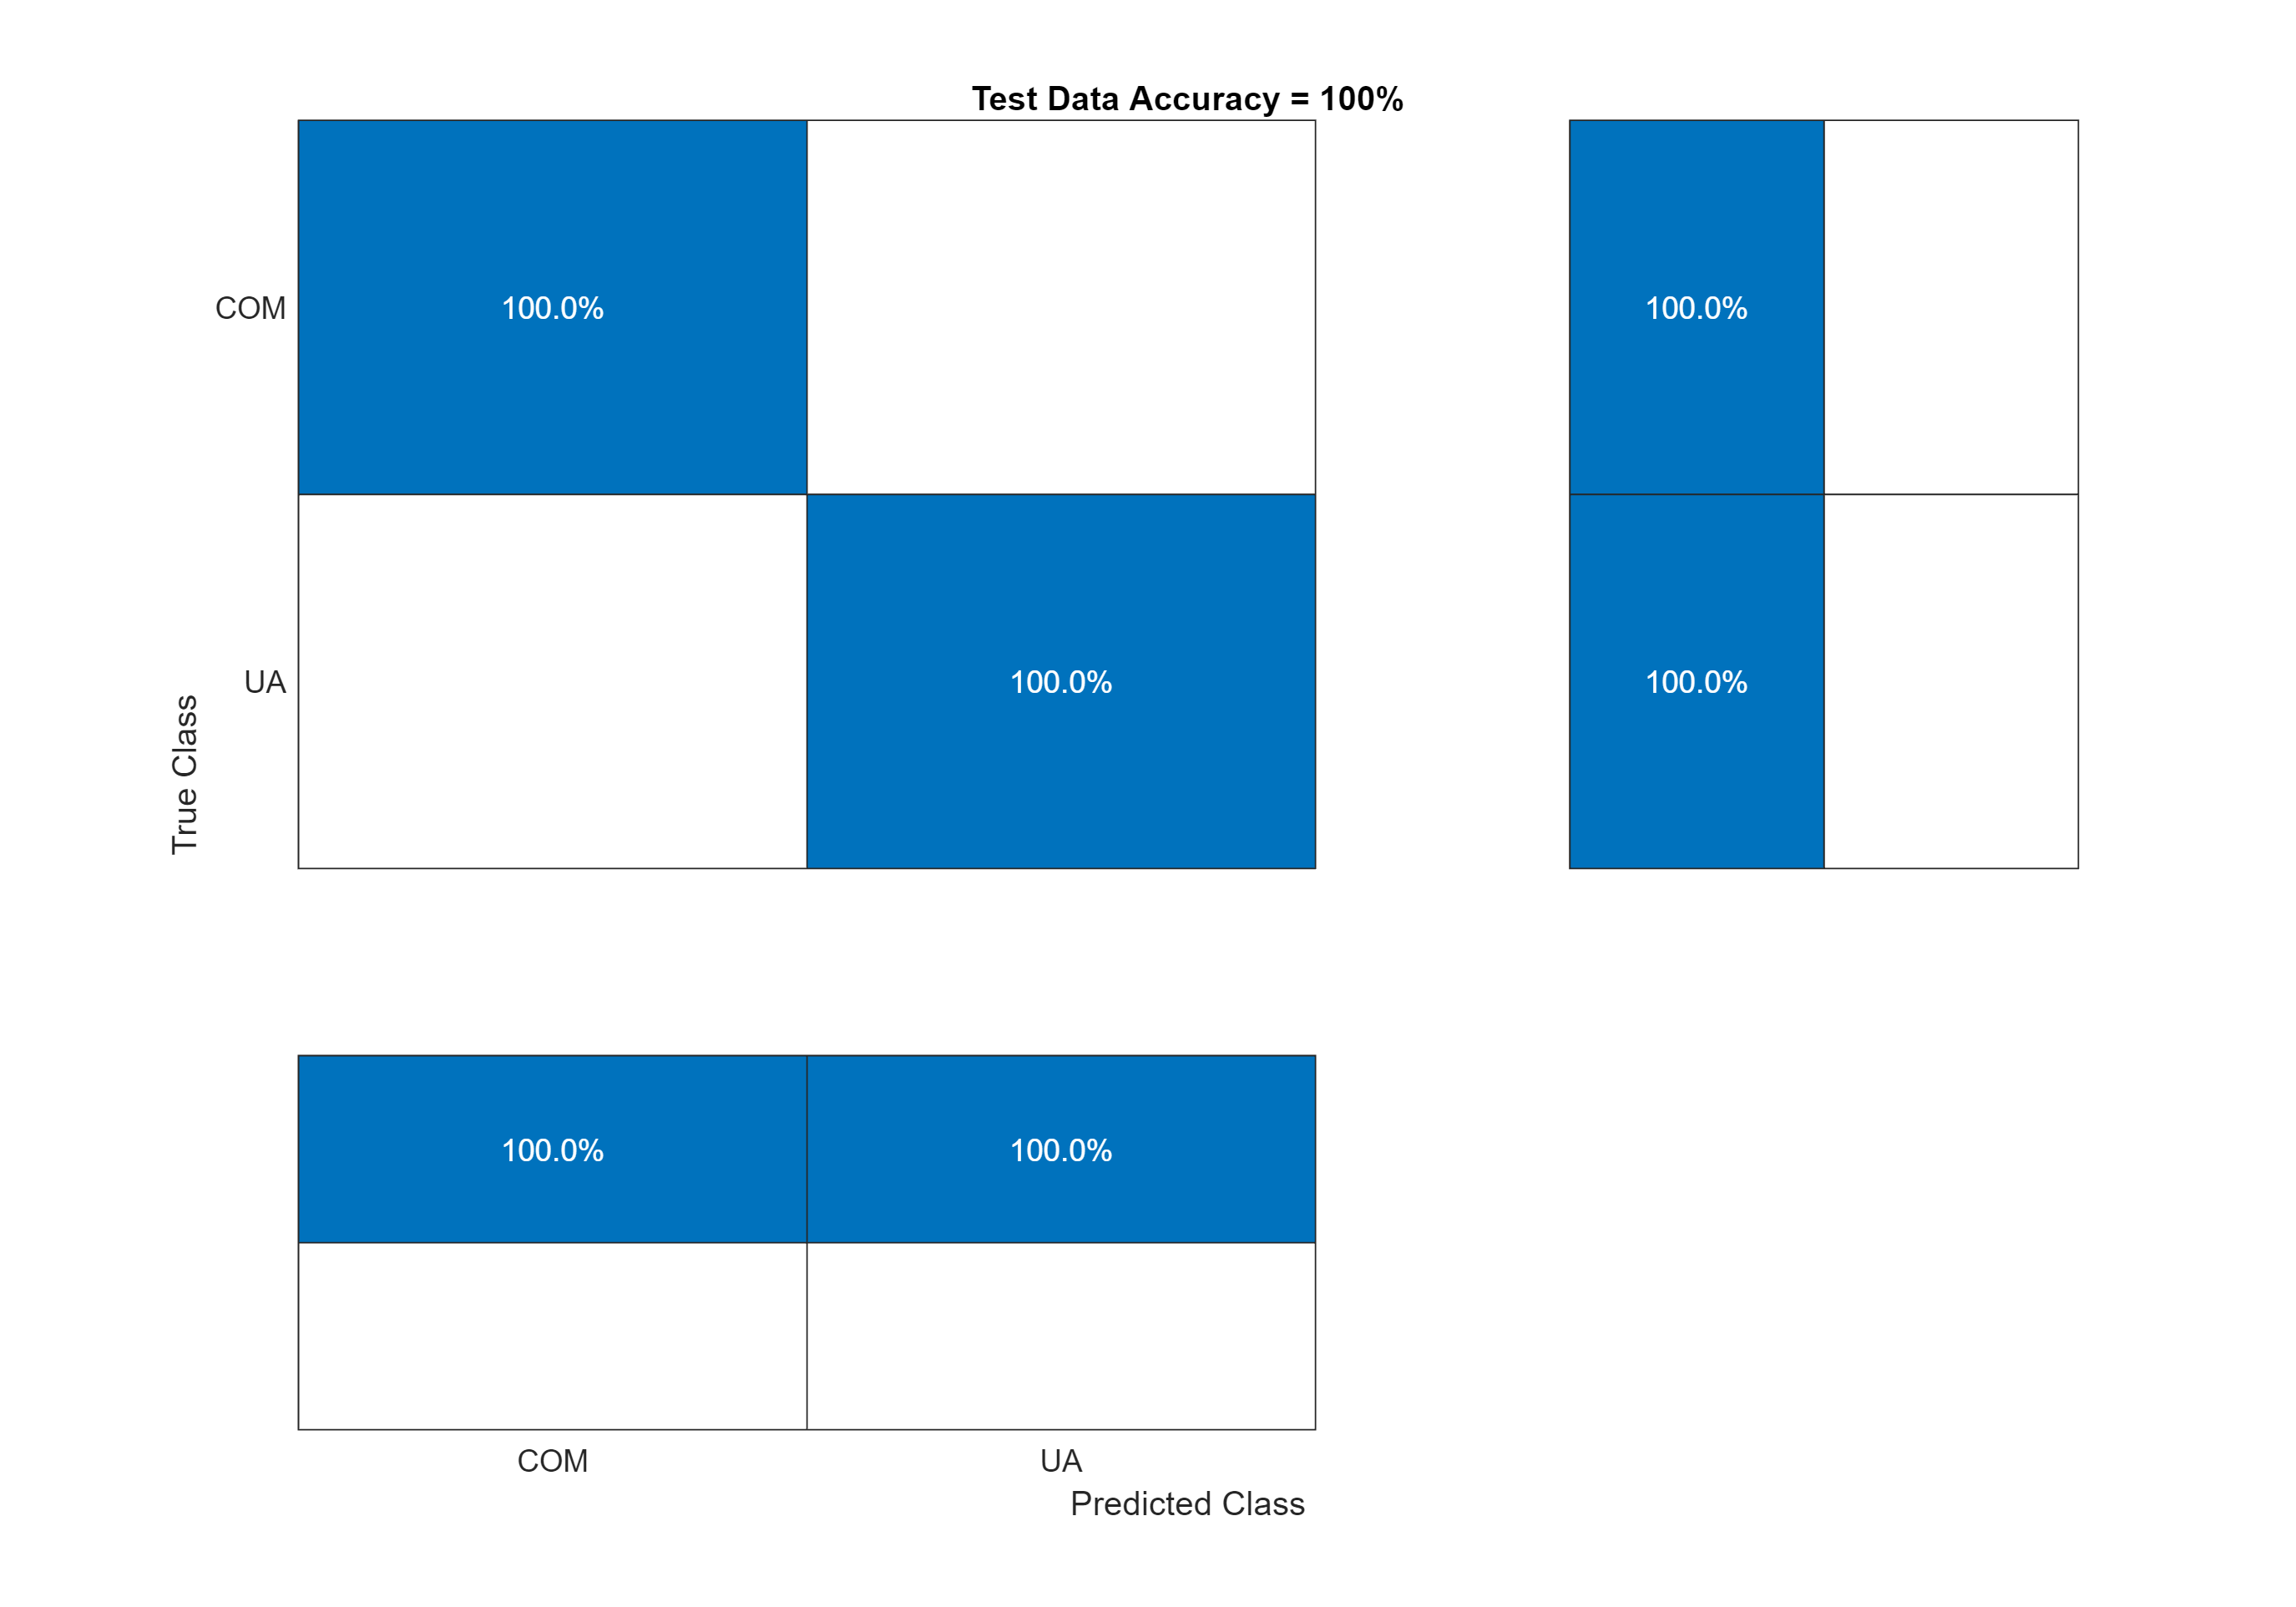

% model1list ={};
% model2list= {};
% fname = {};
for i = 1:length(allIntTimes)

% Train models
% model1 - stone vs non-stone classifier
% model2 - within stones classifier i.e. BEGO vs COM vs UA
%splitn = cell(1,2);
[model1, model2] = ops.trainStoneClassifiers(dataAll, allIntTimes(i));
fname{i} = sprintf('LEDABOFF_%d%s%s%s.mat', allIntTimes(i), datadescription, distanceRange,datestr(now,'mm_dd_yyyy_HH_MM'));
model1list{i} = model1;
model2list{i} = model2;
end

% for i = 1:length(allIntTimes)
% 
% % Train models
% % model1 - stone vs non-stone classifier
% % model2 - within stones classifier i.e. BEGO vs COM vs UA
% [model1, model2] = ops.trainStoneClassifiers(dataAll, allIntTimes(i));
% end
toc

Elapsed time is 183.892088 seconds.


### ROC curve

% Plot ROC for model 1
% ops.plotROC(model1.Info.AUCOnTest)

% Plot ROC for model 2
% ops.plotROC(model2.Info.AUCOnTest)

filename = "D:\April_17_2023\P12484-master-stoneID_classification\stoneID_classification\Prestine fibers\LEDABOFF_1AvgcleavedBB@3mmTwoToFour11_06_2023_22_22.mat"

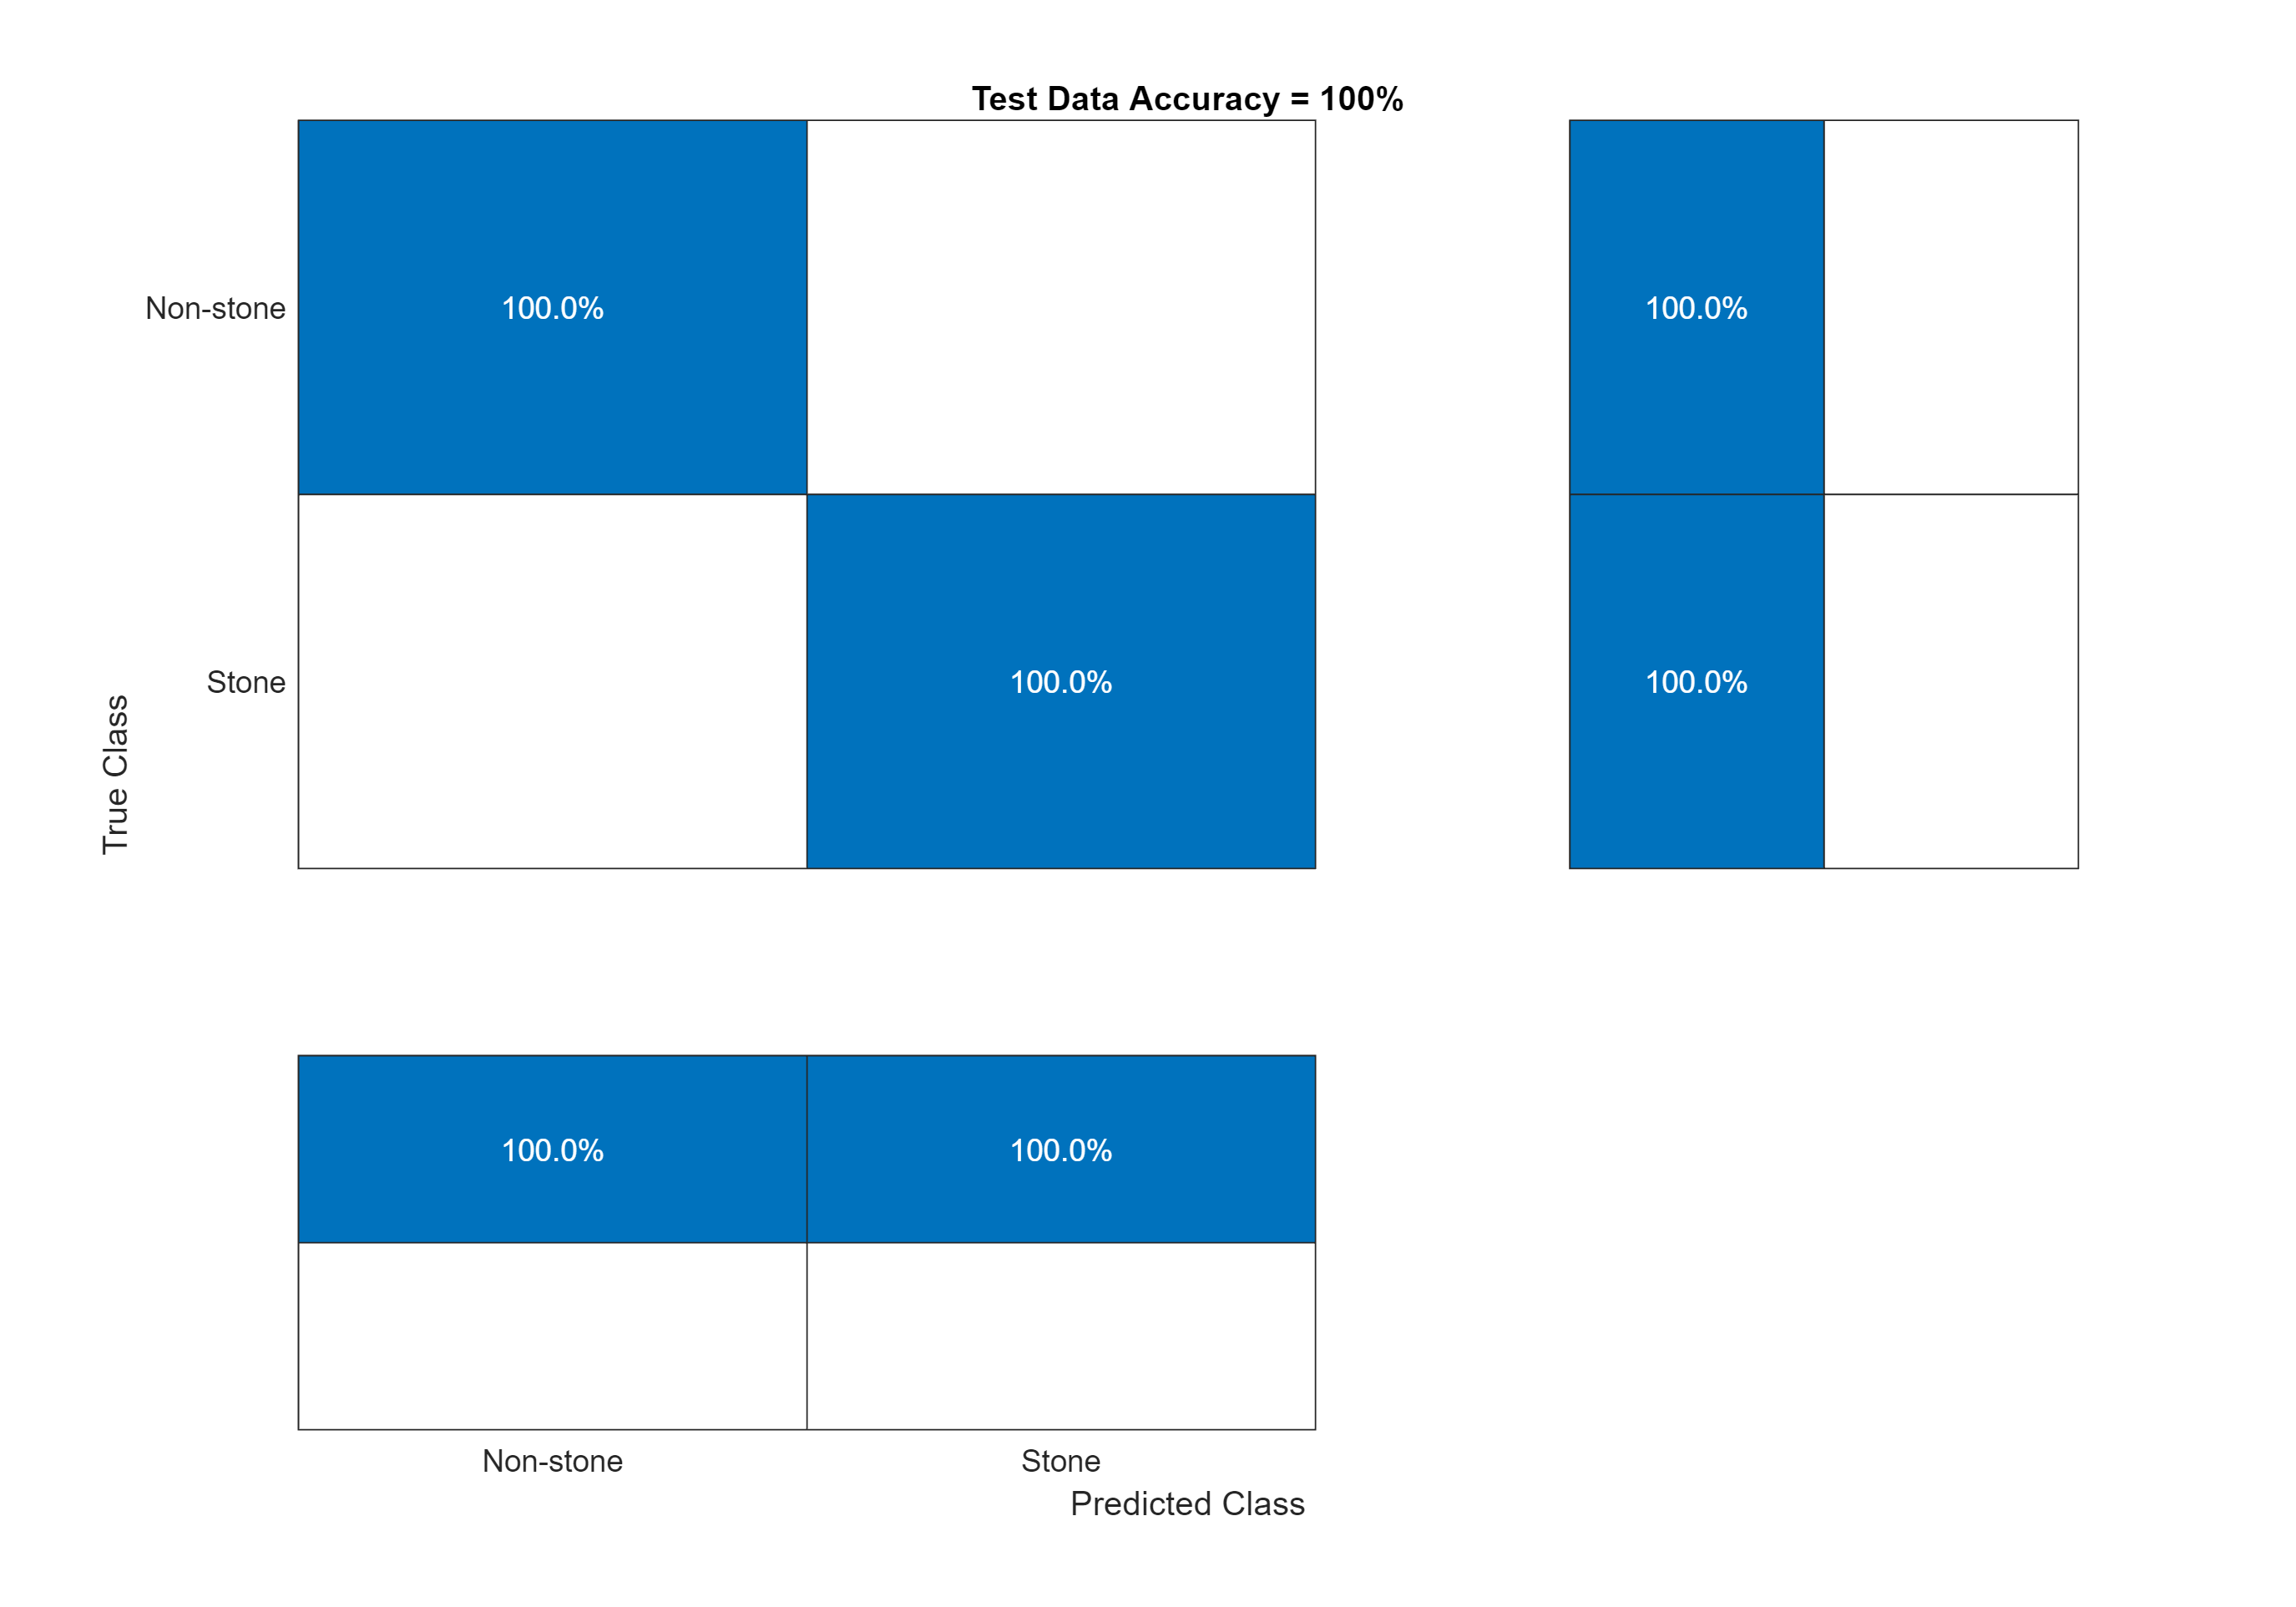

confidence = 210×2 table
    Non-stone     Stone 
    _________    _______

     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894
     0.73106     0.26894


confidence2 = 60×2 table
      COM         UA   
    _______    ________

    0.80696     0.19304
    0.73549     0.26451
     0.7716      0.2284
    0.61695     0.38305
    0.76384     0.23616
    0.79106     0.20894
    0.73435     0.26565
    0.85614     0.14386
    0.89026     0.10974
    0.77403     0.22597
    0.80018     0.19982
    0.82057     0.17943
    0.88327     0.11673
    0.93892     0.06108
    0.94859    0.051414
    0.29476     0.70524


stats = 9×4 table
          name          classes    macroAVG    microAVG
    ________________    _______    ________    ________

    "true_positive"     1    1        1           1    
    "false_positive"    0    0        0           0    
    "false_negative"    0    0        0           0    
    "true_negative"     1    1        1           1    
    "precision"         1    1        1           1    
    "sensitivity"       1    1        1           1    
    "specificity"       1    1        1           1    
    "accuracy"          1    1        1           1    
    "F-measure"         1    1        1           1    


stats = 9×4 table
          name          classes    macroAVG    microAVG
    ________________    _______    ________    ________

    "true_positive"     1    1        1           1    
    "false_positive"    0    0        0           0    
    "false_negative"    0    0        0           0    
    "true_negative"     1    1        1           1    
    "precision"         1    1        1           1    
    "sensitivity"       1    1        1           1    
    "specificity"       1    1        1           1    
    "accuracy"          1    1        1           1    
    "F-measure"         1    1        1           1    


sensitivity1 = 1×2 table
    Non-stone    Stone
    _________    _____

        1          1  


specificity1 = 1×2 table
    Non-stone    Stone
    _________    _____

        1          1  


sensitivity = 1×2 table
    COM    UA
    ___    __

     1     1 


specificity = 1×2 table
    COM    UA
    ___    __

     1     1 



dir = "D:\April_17_2023\P12484-master-stoneID_classification\stoneID_classification\Prestine fibers";

for j = 1:length(allIntTimes)
model1 = model1list{j};
model2 = model2list{j};
filename = fullfile(dir, fname{j})
save(filename, "model1", "model2")
[cm, result] = CMprediction(model1, model1.dataTest);
[cm2, result2] = CMprediction(model2, model2.dataTest);

confidence = result.Scores
confidence2 = result2.Scores
beep on
beep
matrix1=cm.NormalizedValues;
labels1=string(cm.ClassLabels);
statsmatix1= statsOfMeasure(matrix1,1);

if x1==1  

sensitivity1{x1,:}= statsmatix1.classes(6,:);
specificity1{x1,:}= statsmatix1.classes(7,:);
sensitivity1.Properties.VariableNames =labels1;
specificity1.Properties.VariableNames =labels1;

else 

sensitivity1{x1,:}= statsmatix1.classes(6,:);
specificity1{x1,:}= statsmatix1.classes(7,:);

end 
x1=x1+1;

matrix=cm2.NormalizedValues;
labels=string(cm2.ClassLabels);
statsmatix= statsOfMeasure(matrix,1);

if x==1  

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity.Properties.VariableNames =labels;
specificity.Properties.VariableNames =labels;

else 

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);

end 
x=x+1;
sensitivity1
specificity1

sensitivity
specificity
%
end

datestr(now, 'dd/mm/yy-HH:MM')

ans = '06/11/23-22:22'

toc

Elapsed time is 196.938896 seconds.


% Load or create your table 'Probabilities' with columns for each class's probabilities

% % Extract probabilities from the table
% class_probs = table2array(confidence2(:, 2:end)); % Assuming the first column is instance IDs
% 
% % Number of classes
% num_classes = size(class_probs, 2);
% 
% % Load the class names or generate class labels if not available
% class_names = cellstr(num2str((1:num_classes)', 'Class %d'));
% 
% % Create separate histograms for each class's confidence distribution
% for class_idx = 1:num_classes
%     class_probs_column = class_probs(:, class_idx);
%     
%     % Create a new figure for each class
%     figure;
%     
%     % Create histogram
%     histogram(class_probs_column, 'Normalization', 'probability', 'BinWidth', 0.1);
%     
%     title(['Confidence Distribution for ' class_names{class_idx}]);
%     xlabel('Predicted Probability');
%     ylabel('Probability Density');
% end

% % Extract scores from the table
% class_a_scores = confidence2.COM;
% class_b_scores = confidence2.UA;
% 
% % Create histograms for class A and class B confidence distributions
% figure;
% 
% subplot(1, 2, 1);
% histogram(class_a_scores, 'Normalization', 'probability', 'BinWidth', 0.1);
% title('Class A Confidence Distribution');
% xlabel('Scores');
% ylabel('Probability Density');
% 
% subplot(1, 2, 2);
% histogram(class_b_scores, 'Normalization', 'probability', 'BinWidth', 0.1);
% title('Class B Confidence Distribution');
% xlabel('Scores');
% ylabel('Probability Density');